# PROYECTO IMAGEN

## T1: Mejora de color

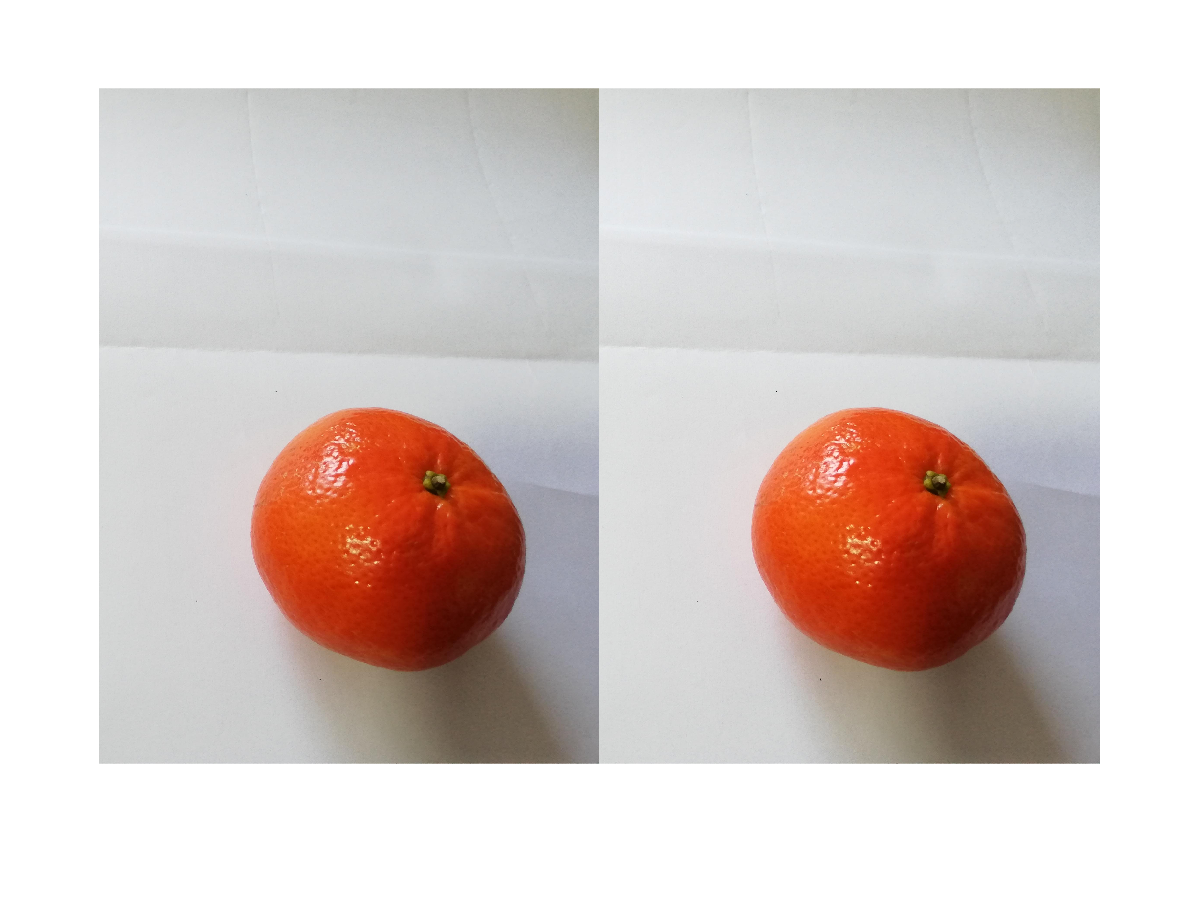

% Leo imagen y convierto a double
imagen = imread('F11.jpg');
imagen_contrastada = MejoraDeColor(imagen);

- [function imagen_contrastada = MejoraDeColor(imagen)](http://m_de9d4f8c)

Esta función utiliza estas dos funciones:

-     [function imbn = ImagenGrises(imc)](http://m_de9d4f8c)

-     [function imagen_contrastada = MaxContraste(imagen, imagen_gris)](http://m_ceb2f39e)

## T2: Segmentación

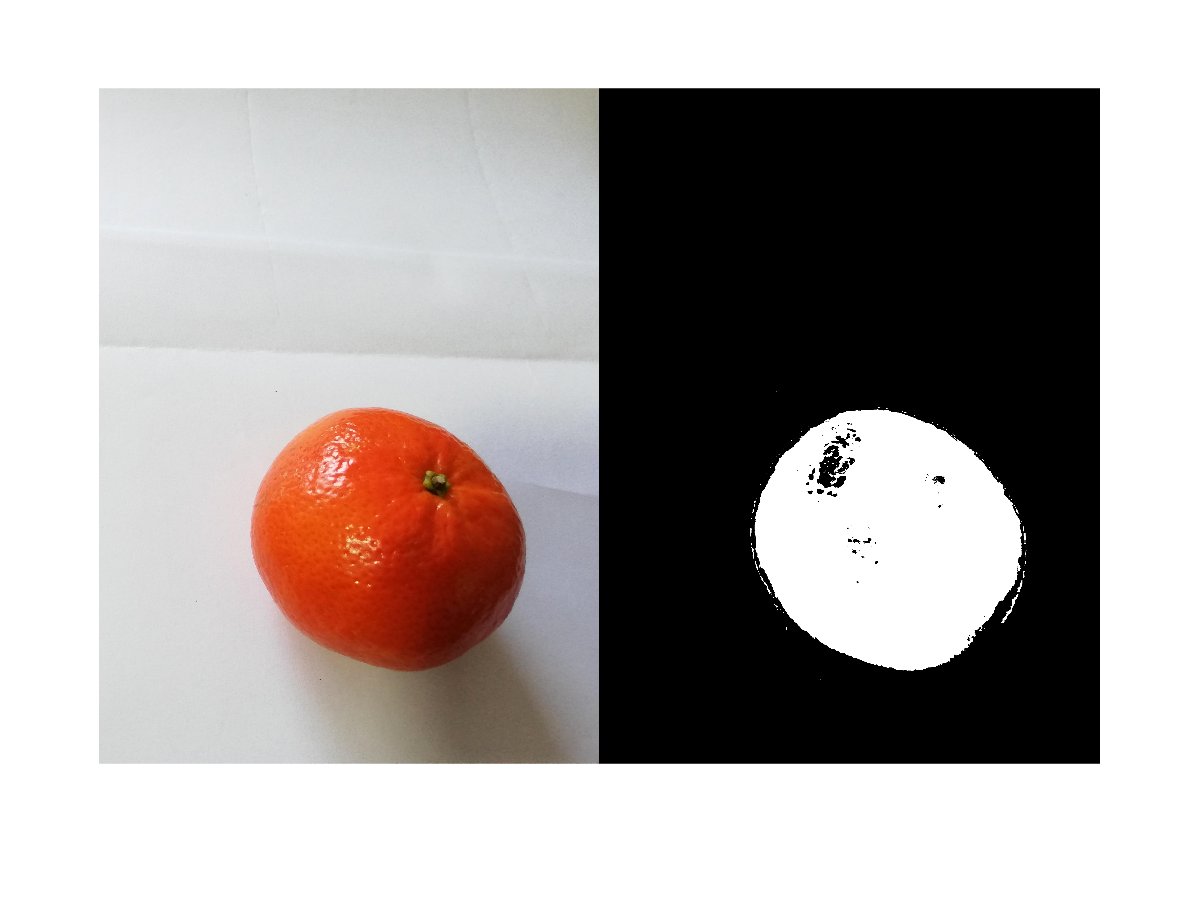

imagen_segmentada = Segmentacion(imagen_contrastada);

- [function imagen_segmentada = Segmentacion(image_contrastada)](http://m_cdd6e05f)

## T3: Extracción de características

prototipo = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada)

prototipo =     0.7047    0.2139    0.0800


- [function prototipo = ExtraccionCaracteristica(imagen_contratada, imagen_segmentada)](http://m_d03f4a2d)

## T4: Creación de un alfabeto

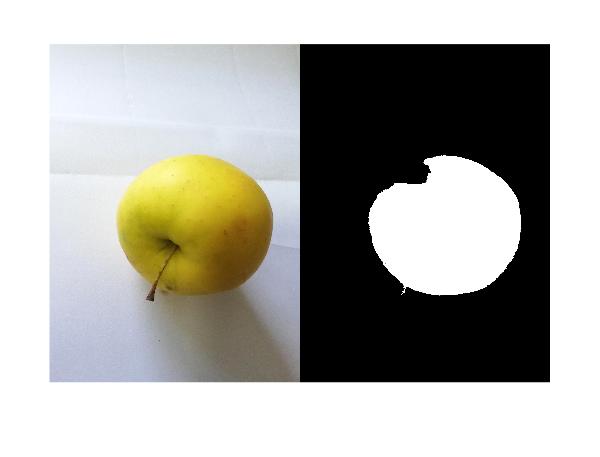

prototipo_manzanas =     0.6949    0.5848    0.1269


% Imagenes de manzanas:
imagen_1_manzana = imread('F01.jpg');
imagen_2_manzana = imread('F02.jpg');
imagen_3_manzana = imread('F03.jpg');
% Vector prototipo de las manzanas:
prototipo_manzanas = PromedioTotal(imagen_1_manzana,imagen_2_manzana,imagen_3_manzana)

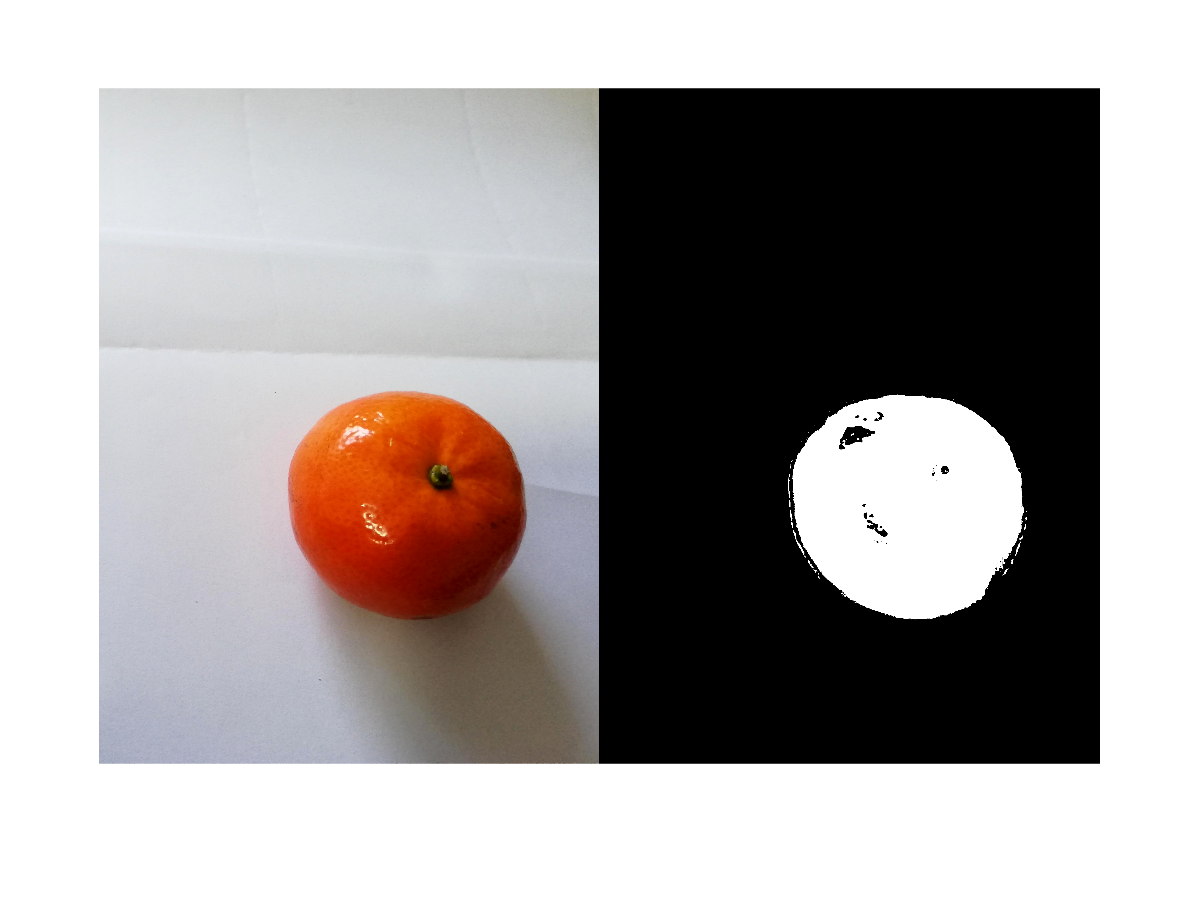

prototipo_mandarinas =     0.7088    0.2217    0.0520



% Imagenes de mandarinas:
imagen_1_mandarina = imread('F07.jpg');
imagen_2_mandarina = imread('F08.jpg');
imagen_3_mandarina = imread('F09.jpg');
% Vector prototipo de todas las mandarinas:
prototipo_mandarinas =  PromedioTotal(imagen_1_mandarina,imagen_2_mandarina,imagen_3_mandarina)

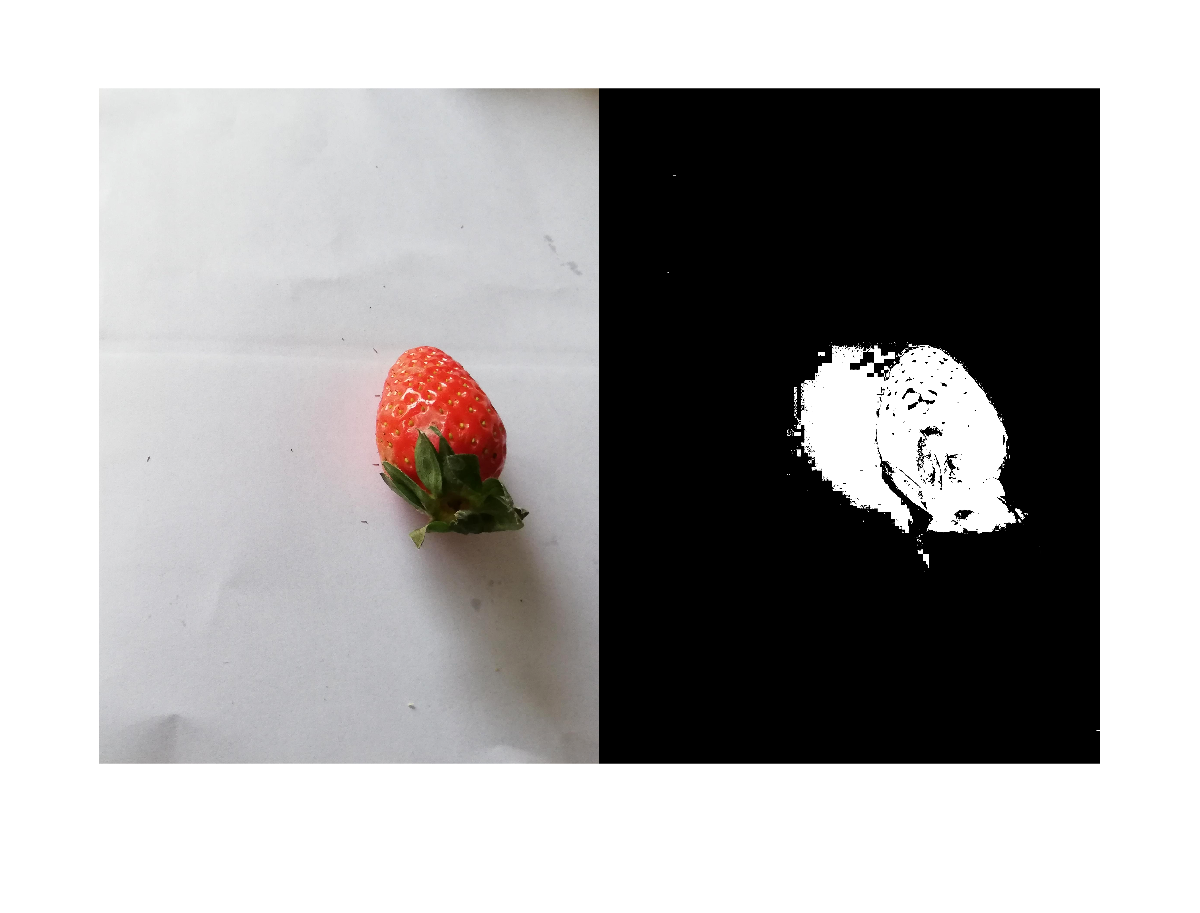

prototipo_fresas =     0.5531    0.2628    0.2201



% Imagenes de fresas:
imagen_1_fresa = imread('F13.jpg');
imagen_2_fresa = imread('F17.jpg');
imagen_3_fresa = imread('F18.jpg');
% Vector prototipo de todas las fresas:
prototipo_fresas = PromedioTotal(imagen_1_fresa,imagen_2_fresa,imagen_3_fresa)

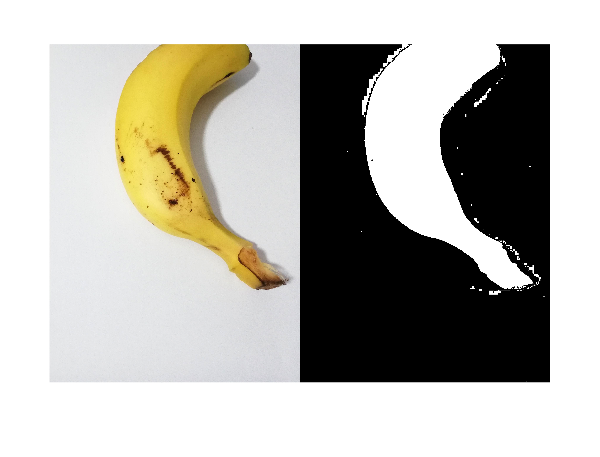

prototipo_platanos =     0.7952    0.6925    0.2999



% Imagenes de platanos:
imagen_1_platano = imread('F19.jpg');
imagen_2_platano = imread('F20.jpg');
imagen_3_platano = imread('F21.jpg');
% Vector prototipo de todos los platanos:
prototipo_platanos = PromedioTotal(imagen_1_platano,imagen_2_platano,imagen_3_platano)

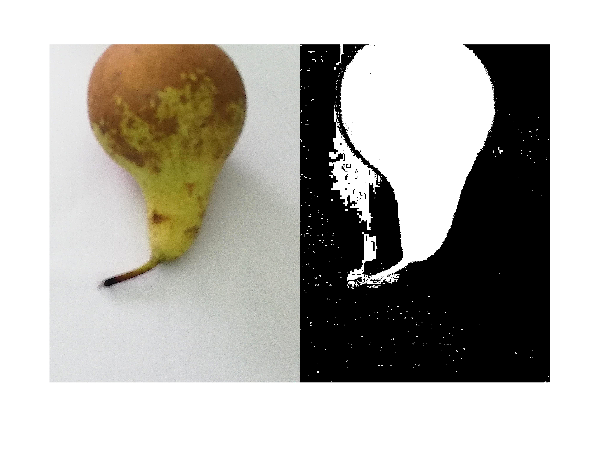

prototipo_peras =     0.5888    0.4599    0.2271



% Imagenes de peras:
imagen_1_pera = imread('F25.jpg');
imagen_2_pera = imread('F26.jpg');
imagen_3_pera = imread('F27.jpg');
% Vector prototipo de todas las peras:
prototipo_peras = PromedioTotal(imagen_1_pera,imagen_2_pera,imagen_3_pera)

- [promedio  = PromedioTotal(imagen_1,imagen_2,imagen_3)](http://m_b688a51a)

## T5: Diseño de una función de reconocimiento

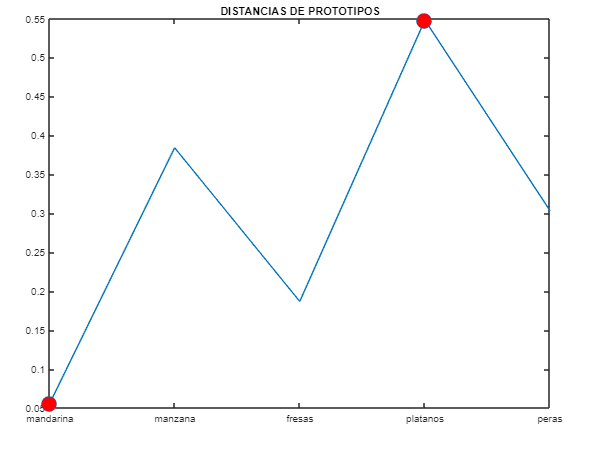

La fruta a la que más se parece es:Mandarina
La fruta a la que menos se parece es:Platano
ES UNA MANDARINA


tipo_fruta = 2

imagen_entrada = imread('F12.jpg');
tipo_fruta = ReconocerFruta(imagen_entrada,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

- [tipo_fruta = ReconocerFruta(imagen_entrada, prototipo_mandarinas, prototipo_manzanas, prototipo_fresas, prototipo_platanos, prototipo_peras)](http://m_b61344de)

## T6: Prueba

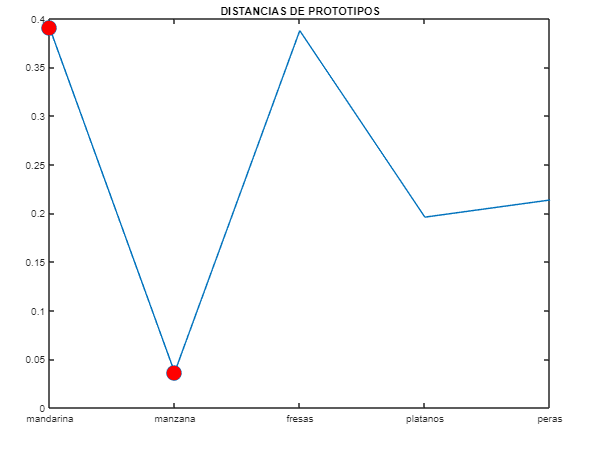

La fruta a la que más se parece es:Manzana
La fruta a la que menos se parece es:Mandarina
ES UNA MANZANA


fruta = 1

matriz_ceros = zeros(5); %la dimensión es la clase de frutas que hay
imagen_prueba = imread('F04.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_ceros,fruta,1)

matriz_confusion =      1     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


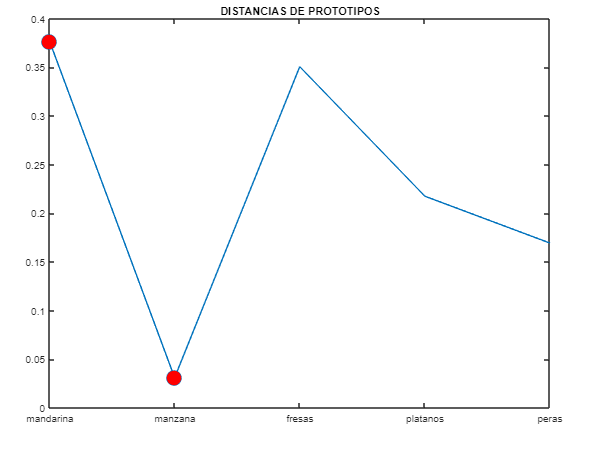

La fruta a la que más se parece es:Manzana
La fruta a la que menos se parece es:Mandarina
ES UNA MANZANA


fruta = 1

imagen_prueba= imread('F05.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,1)

matriz_confusion =      2     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


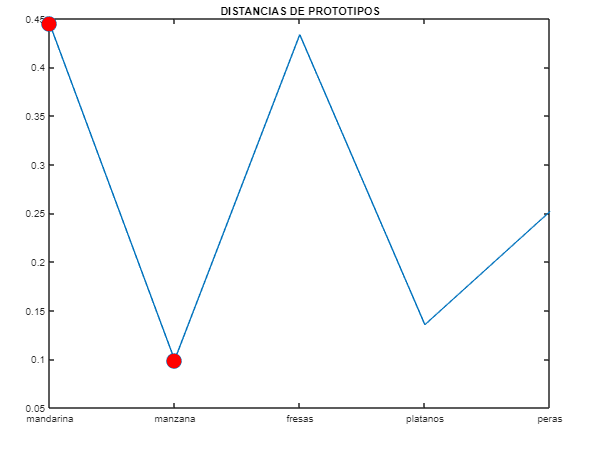

La fruta a la que más se parece es:Manzana
La fruta a la que menos se parece es:Mandarina
ES UNA MANZANA


fruta = 1

imagen_prueba= imread('F06.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,1)

matriz_confusion =      3     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


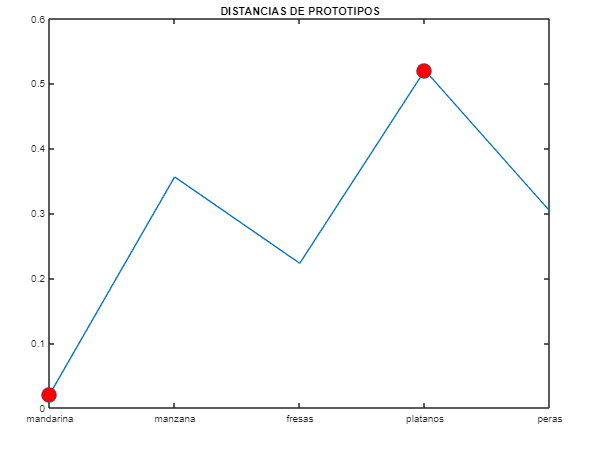

La fruta a la que más se parece es:Mandarina
La fruta a la que menos se parece es:Platano
ES UNA MANDARINA


fruta = 2

imagen_prueba= imread('F10.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,2)

matriz_confusion =      3     0     0     0     0
     0     1     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


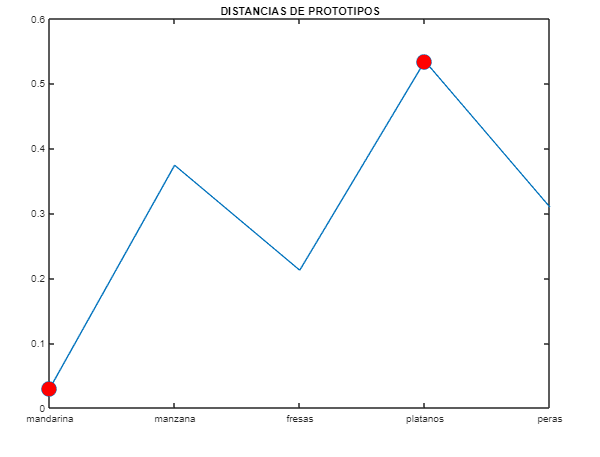

La fruta a la que más se parece es:Mandarina
La fruta a la que menos se parece es:Platano
ES UNA MANDARINA


fruta = 2

imagen_prueba= imread('F11.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,2)

matriz_confusion =      3     0     0     0     0
     0     2     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


La fruta a la que más se parece es:Mandarina
La fruta a la que menos se parece es:Platano
ES UNA MANDARINA


fruta = 2

imagen_prueba= imread('F12.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,2)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


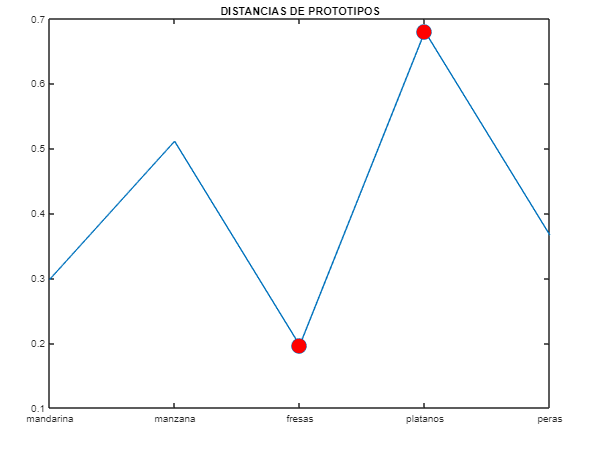

La fruta a la que más se parece es:Fresa
La fruta a la que menos se parece es:Platano
ES UNA FRESA


fruta = 3

imagen_prueba= imread('F14.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,3)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     1     0     0
     0     0     0     0     0
     0     0     0     0     0


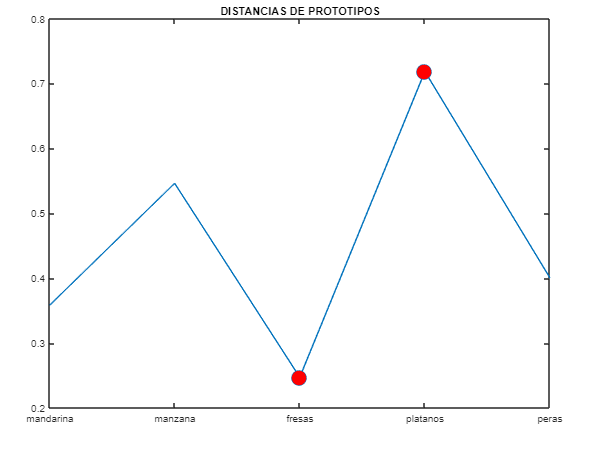

La fruta a la que más se parece es:Fresa
La fruta a la que menos se parece es:Platano
ES UNA FRESA


fruta = 3

imagen_prueba= imread('F15.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,3)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     2     0     0
     0     0     0     0     0
     0     0     0     0     0


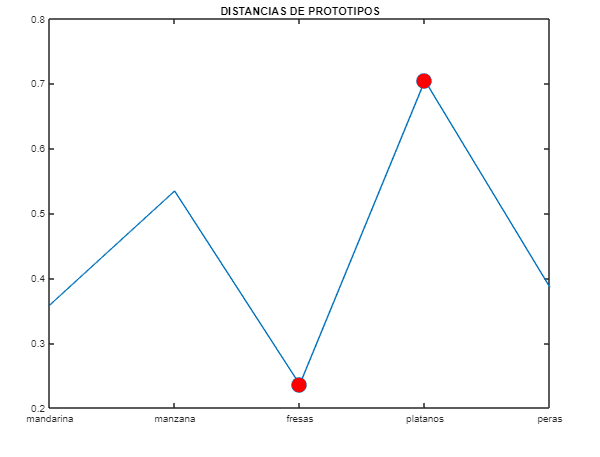

La fruta a la que más se parece es:Fresa
La fruta a la que menos se parece es:Platano
ES UNA FRESA


fruta = 3

imagen_prueba= imread('F16.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,3)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     0     0
     0     0     0     0     0


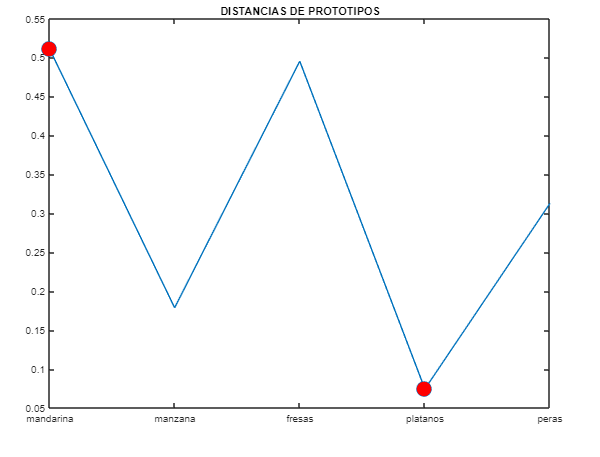

La fruta a la que más se parece es:Platano
La fruta a la que menos se parece es:Mandarina
ES UN PLATANO


fruta = 4

imagen_prueba= imread('F22.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,4)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     1     0
     0     0     0     0     0


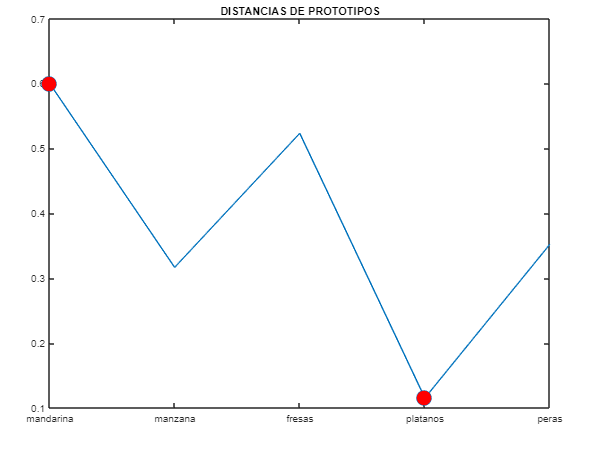

La fruta a la que más se parece es:Platano
La fruta a la que menos se parece es:Mandarina
ES UN PLATANO


fruta = 4

imagen_prueba= imread('F23.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,4)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     2     0
     0     0     0     0     0


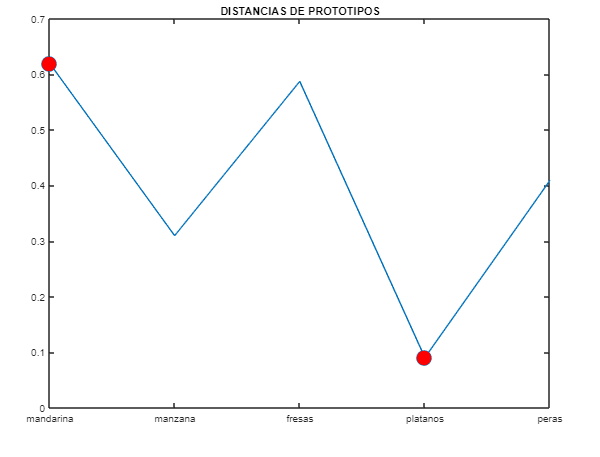

La fruta a la que más se parece es:Platano
La fruta a la que menos se parece es:Mandarina
ES UN PLATANO


fruta = 4

imagen_prueba= imread('F24.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,4)

matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     3     0
     0     0     0     0     0


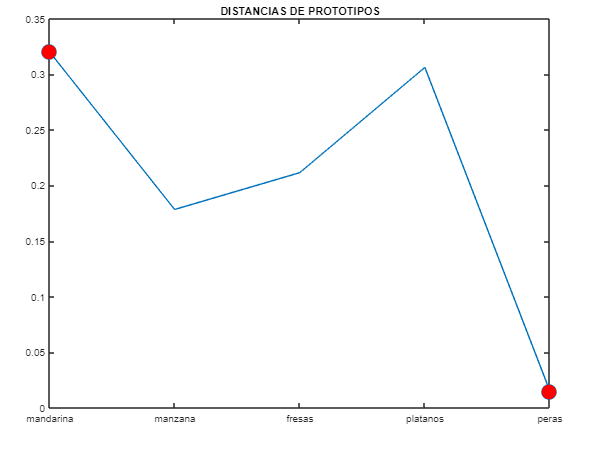

La fruta a la que más se parece es:Pera
La fruta a la que menos se parece es:Mandarina


ans = logical
   1


ES UNA PERA


fruta = 5

imagen_prueba= imread('F28.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,5)

ans = logical
   1


matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     3     0
     0     0     0     0     1


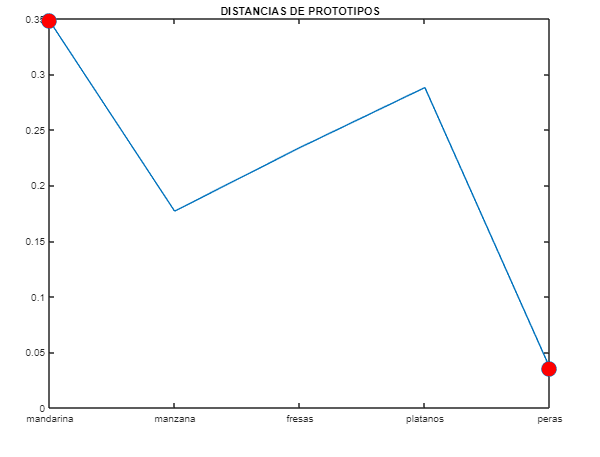

La fruta a la que más se parece es:Pera
La fruta a la que menos se parece es:Mandarina


ans = logical
   1


ES UNA PERA


fruta = 5

imagen_prueba= imread('F29.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,5)

ans = logical
   1


matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     3     0
     0     0     0     0     2


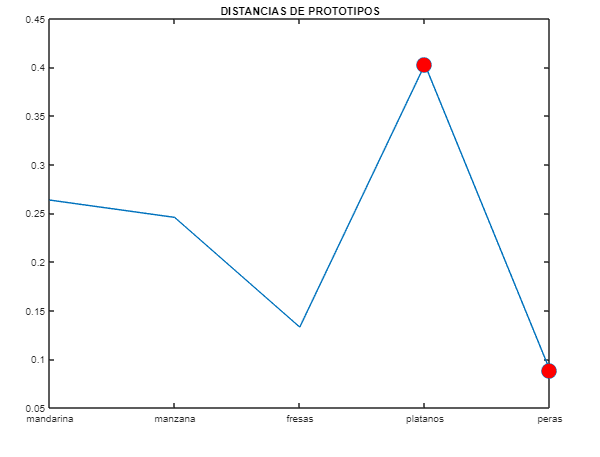

La fruta a la que más se parece es:Pera
La fruta a la que menos se parece es:Platano


ans = logical
   1


ES UNA PERA


fruta = 5

imagen_prueba= imread('F30.jpg');
fruta = ReconocerFruta(imagen_prueba,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)

matriz_confusion = MatrizConfusion(matriz_confusion,fruta,5)

ans = logical
   1


matriz_confusion =      3     0     0     0     0
     0     3     0     0     0
     0     0     3     0     0
     0     0     0     3     0
     0     0     0     0     3


- [matriz_confusion = MatrizConfusion(matriz_confusion,fruta,n)](http://m_948810c7)

## FUNCIONES:

## Tarea 1

- **funcion imagen_contrastada = MejoraDeColor(imagen)**

function imagen_contrastada = MejoraDeColor(imagen)
    imagen = im2double(imagen);

    %Convierto a escala de grises
    imagen_grises = ImagenGrises(imagen); %también se podría hacer con  rgb2gray(imagen)

    % Maximización del contraste
    imagen_contrastada = MaxContraste(imagen, imagen_grises);

    % Visualización de la mejora de color
    comparacion = [imagen imagen_contrastada];
    imshow(comparacion);
end

- **function imbn = ImagenGrises(imc)**

function imbn = ImagenGrises(imc)
    R = imc(:,:,1);
    G = imc(:,:,2);
    B = imc(:,:,3);
    
    Y = 0.3*R+0.59*G+0.11*B;    % Calculo Y
    % Para que esté en escala de grises --> Y = R = G = B
    imbn(:,:,1) = Y;    % R = Y
    imbn(:,:,2) = Y;    % G = Y
    imbn(:,:,3) = Y;    % B = Y
end

- **function imagen_contrastada = MaxContraste(imagen, imagen_gris)**

function imagen_contrastada = MaxContraste(imagen, imagen_gris)
    imagen = im2double(imagen);
    imagen_gris = im2double(imagen_gris);

    min_luminancia = min(min(imagen_gris));            % Mínimo de luminancia
    max_luminancia = max(max(imagen_gris));            % Máximo de luminancia  
    
    imagen_contrastada = ((imagen - min_luminancia)./(max_luminancia-min_luminancia))*1 + 0;  % Operación máximo contraste    
end

## Tarea 2

- **imagen_segmentada = Segmentacion(imagen_contrastada)**

function imagen_segmentada = Segmentacion(imagen_contrastada)
    imagen = imagen_contrastada;
    imagen_hsv = rgb2hsv(imagen);  %% convertir a color
    %imshow([imagen imagen_hsv]);
    imagen_hsv_gris = ImagenGrises(imagen_hsv); 
    %imshow([imagen_hsv imagen_hsv_gris]);
    S = imagen_hsv(:,:,2); % esto es para asignar S
    level = graythresh(S); % aplicar umbral con esta función de matlab
    BW = im2double(imbinarize(imagen_hsv_gris,level)); % crea una imagen binaria a partir de la imagen
    imshow([imagen BW]);
    imagen_segmentada = BW;
end

## Tarea 3

- **prototipo = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada)**

function prototipo = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada)
    M = imagen_segmentada(:,:,2);

    R = imagen_contrastada(:,:,1);
    G = imagen_contrastada(:,:,2);
    B = imagen_contrastada(:,:,3);
    
    frutaR = mean(R(M == 1)); %los valores medios
    frutaG = mean(G(M == 1));
    frutaB= mean(B(M == 1));
    
    prototipo = [frutaR frutaG frutaB];
end

## Tarea 4

- **promedio  = PromedioTotal(imagen_1,imagen_2,imagen_3)**

function promedio = PromedioTotal(imagen_1,imagen_2,imagen_3)
    
    imagen_contrastada = MejoraDeColor(imagen_1);
    imagen_segmentada = Segmentacion(imagen_contrastada);
    prototipo_1 = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada);

    imagen_contrastada = MejoraDeColor(imagen_2);
    imagen_segmentada = Segmentacion(imagen_contrastada);
    prototipo_2 = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada);

    imagen_contrastada = MejoraDeColor(imagen_3);
    imagen_segmentada = Segmentacion(imagen_contrastada);
    prototipo_3 = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada);

    matriz = [prototipo_1;prototipo_2;prototipo_3];
    
    promedio = mean(matriz);

end

## Tarea 5

- **tipo_fruta = ReconocerFruta(imagen_entrada, prototipo_mandarinas, prototipo_manzanas, prototipo_fresas, prototipo_platanos, prototipo_peras)**

function tipo_fruta = ReconocerFruta(imagen_entrada,prototipo_mandarinas,prototipo_manzanas,prototipo_fresas,prototipo_platanos,prototipo_peras)
    % prototipos = promedios totales
    imagen_contrastada = MejoraDeColor(imagen_entrada);
    imagen_segmentada = Segmentacion(imagen_contrastada);
    caracteristicas_entrada = ExtraccionCaracteristica(imagen_contrastada, imagen_segmentada);
    
    % Calculo de la distancia entre dos vectores = modulo(X-Y) --> Distancia de X a Y
    distancia_mandarinas = norm(prototipo_mandarinas-caracteristicas_entrada);  % Calculo el módulo del vector (la norma)
    distancia_manzanas = norm(prototipo_manzanas-caracteristicas_entrada);
    distancia_fresas = norm(prototipo_fresas-caracteristicas_entrada);
    distancia_platanos = norm(prototipo_platanos-caracteristicas_entrada);
    distancia_peras = norm(prototipo_peras-caracteristicas_entrada);

    distancias = [distancia_mandarinas distancia_manzanas distancia_fresas distancia_platanos distancia_peras];
    % La distancia minima
    minimo = min (distancias);
    grafico(distancias);

    if minimo == distancia_manzanas   
        disp('ES UNA MANZANA');
        tipo_fruta = 1;

    elseif  minimo == distancia_mandarinas
       disp('ES UNA MANDARINA');
       tipo_fruta = 2;

    elseif  minimo == distancia_fresas
        disp('ES UNA FRESA');
        tipo_fruta = 3;

    elseif  minimo == distancia_platanos
        disp('ES UN PLATANO');
        tipo_fruta = 4;

    else minimo == distancia_peras 
        disp('ES UNA PERA');
        tipo_fruta = 5;
        
    end

end

- **function grafico(distancias)**

function grafico(distancias)
    X = distancias;
    minimo = min (X);
    maximo = max (X);
    idxmin = find(X == minimo);
    idxmax = find(X == maximo);
    plot(X, '-o', 'MarkerIndices', [idxmin idxmax], 'MarkerFaceColor','red', 'MarkerSize',10)
    xticks([1 2 3 4 5])
    xticklabels({'mandarina', 'manzana', 'fresas', 'platanos', 'peras'})
    title("DISTANCIAS DE PROTOTIPOS");
    nombres{1} = 'Mandarina';
    nombres{2} = 'Manzana';
    nombres{3} = 'Fresa';
    nombres{4} = 'Platano';
    nombres{5} = 'Pera';
    disp(strcat('La fruta a la que más se parece es: ', nombres{idxmin}));
    disp(strcat('La fruta a la que menos se parece es: ', nombres{idxmax}));
end

## Tarea 6

- **matriz_confusion = MatrizConfusion(matriz_ceros,fruta,n)**

function matriz_confusion = MatrizConfusion(matriz_ceros,fruta,n)

        if fruta == 1
        matriz_ceros(n,1) = matriz_ceros(n,1)+ 1;

        elseif fruta == 2
             matriz_ceros(n,2) = matriz_ceros(n,2) + 1;

        elseif fruta == 3
             matriz_ceros(n,3) = matriz_ceros(n,3) + 1;

        elseif fruta == 4
             matriz_ceros(n,4) = matriz_ceros(n,4) + 1;

        else fruta == 5
             matriz_ceros(n,5) =  matriz_ceros(n,5) + 1;

        end

        matriz_confusion = matriz_ceros;
end